## Grapgh 1: 3D Operating Domian


load('xVapour Pressure.mat');
NAME_FLUID = string(cellfun(@(a) a(str2double(Fluid)+3,3),Pv(1),'UniformOutput',false))

NAME_FLUID = "WATER"

load('xMetal Propoperties Database.mat');
NAME_METAL = string(cellfun(@(a) a(str2double(Metl)+1,20),M2(1),'UniformOutput',false))

NAME_METAL = "Cu"

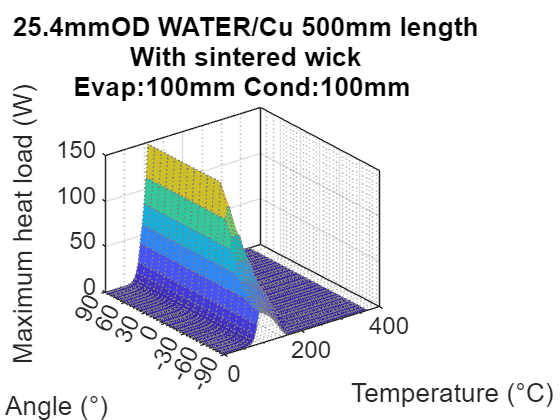


Q2D = [Qcap_m90.';Qcap_m80.';Qcap_m70.';Qcap_m60.';Qcap_m50.';Qcap_m40.';Qcap_m30.';Qcap_m20.';Qcap_m10.';Qcap_0.';Qcap_10.';Qcap_20.';Qcap_30.';Qcap_40.';Qcap_50.';Qcap_60.';Qcap_70.';Qcap_80.';Qcap_90.'];

% Create figure
figure1 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

X3D = T(:,1);
Y3D = theta_range;
Z3D = Q2D;

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

surf(X3D,Y3D,real(Z3D),'Parent',axes1,'LineWidth',0.1,'LineStyle',':',...
    'EdgeColor',[0.501960813999176 0.501960813999176 0.501960813999176]);

% Create zlabel
zlabel('Maximum heat load (W)');

% Create ylabel
ylabel('Angle (°)');

% Create xlabel
xlabel('Temperature (°C)');

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3});

ylim(axes1,[-90 90]);
view(axes1,[-37.5 30]);
grid(axes1,'on');
% Set the remaining axes properties
set(axes1,'YTick',[-90 -60 -30 0 30 60 90],'YTickLabel',...
    {'-90','-60','-30','0','30','60','90'});

box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 2: Power transport limits

% Additional constant
figure2 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure2);
hold(axes1,'on');

%,Qcap_ant
plot1 = plot(T(:,1),[Qb(:,1),Qcap_t(:,1),Qvisc(:,1),Qsonic(:,1),Qent(:,1)],'Parent',axes1);
set(plot1(1),'DisplayName','Qb','LineWidth',2);
%set(plot1(2),'DisplayName','Qcap_{wicked}');
set(plot1(2),'DisplayName','Qcap','LineWidth',2);
set(plot1(3),'DisplayName','Qvisc','LineWidth',2);
set(plot1(4),'DisplayName','Qsonic','LineWidth',2);
set(plot1(5),'DisplayName','Qent','LineWidth',2);

ylabel({'Maximum heat load (W)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel
Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});     

xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
ylim(axes1,[0 max(Q_min+10)]);                    % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')


## Graph 3: dT at capillary limit

figure3 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure3);
hold(axes1,'on');

plot1 = plot(T(:,1),dT_tot,'Parent',axes1);
set(plot1(1),'DisplayName','total dT','LineWidth',2);
%set(plot1(2),'DisplayName','total dT2');

ylabel({'dT (°C)'});                                % Create ylabel
xlabel({'Temperature (°C)'});                              % Create xlabel
Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe dT at max heat flux vs temperature');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});     

%xlim(axes1,[min(P_range) max(P_range)]);            % X-limits of the axes
%ylim(axes1,[0 max(T)]);                         % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northwest');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')


## Figure 4: Total power graph

figure4 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure4);
hold(axes1,'on');

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4}); 

plot1 = plot(T(:,1),Q_min,'Parent',axes1);
set(plot1(1),'DisplayName', strcat(string(NAME_FLUID),{' '},'power limitation'),'LineWidth',2);

ylabel({'Maximum heat load (W)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel   

xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
ylim(axes1,[0 max(Q_min)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')


## Graph 5: Effective conductivity

figure5 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure5);
hold(axes1,'on');

plot1 = plot(T(:,1),K_eff,'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);

ylabel({'Effective conductivity (W/mK)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Heat pipe effective thermal conductivity'});      

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 6: Thermal resistance trend

figure6 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure6);
hold(axes1,'on');

plot1 = plot(T(:,1),Res','Parent',axes1,'LineWidth',2);

ylabel({'Thermal Resistance (K/W)'});                              % Create ylabel
xlabel({'Saturation temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Heat pipe thermal resistance'});  

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

% Create legend
%legend1 = legend(axes1,'show');
%set(legend1,'Location','northeast');

## Graph 7: Heat flux

figure7 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure7);
hold(axes1,'on');

yyaxis left
plot1 = plot(T(:,1),[q_evap,q_cond,q_axial],'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);
set(plot1(2),'DisplayName','Condenser heat flux','LineWidth',2);
set(plot1(3),'DisplayName','Axial heat flux','LineWidth',2);

ylabel({'Heat flux (W/m2)'});   

yyaxis right
plot1 = plot(T(:,1),Q_min,'Parent',axes1);
set(plot1(1),'DisplayName','Power limitation curve');


ylabel({'Maximum heat load (W)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});     

xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 8: Cappillary limit at angles

% Additional constant
figure8 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure8);
hold(axes1,'on');

plot1 = plot(T(:,1),[Qcap_m90,Qcap_m60,Qcap_m30,Qcap_0,Qcap_30,Qcap_60,Qcap_90],'Parent',axes1);
set(plot1(1),'DisplayName','-90°','LineWidth',2);
set(plot1(2),'DisplayName','-60°','LineWidth',2);
set(plot1(3),'DisplayName','-30°','LineWidth',2);
set(plot1(4),'DisplayName','0°','LineWidth',2);
set(plot1(5),'DisplayName','30°','LineWidth',2);
set(plot1(6),'DisplayName','60°','LineWidth',2);
set(plot1(7),'DisplayName','90°','LineWidth',2);

ylabel({'Maximum heat load (W)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                       % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Heat pipe capilliary limit curves at various angles'});

xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
ylim(axes1,[0 max(Qcap_90+10)]);                    % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 9: Nucleation radius trend

sz_qevap = size(q_evap);

for x = 1:sz_qevap(1);
    
r_n = sqrt((((st_l(:,1).*T(:,1)).*K_l(:,1)).*(rho_v(:,1).^-1-rho_l(:,1).^-1))./(lhc(:,1)*(q_evap(x))));

R_n(:,x) = r_n;

end

sz_q = size(q_evap);
spacing = round(linspace(1,sz_q(1),6));

figure9 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure9);
hold(axes1,'on');

plot1 = plot(T(:,1),[R_n(:,spacing(1)),R_n(:,spacing(2)),R_n(:,spacing(3)),R_n(:,spacing(4)),R_n(:,spacing(5)),R_n(:,spacing(6))],'Parent',axes1);
set(plot1(1),'DisplayName','Evap 6.3e+04 W/m2','LineWidth',2);
set(plot1(2),'DisplayName','Evap 5.9e+04 W/m2','LineWidth',2);
set(plot1(3),'DisplayName','Evap 3.2+04 W/m2','LineWidth',2);
set(plot1(4),'DisplayName','Evap 1.1e+04 W/m2','LineWidth',2);
set(plot1(5),'DisplayName','Evap 3000 W/m2','LineWidth',2);
set(plot1(6),'DisplayName','Evap 600 W/m2','LineWidth',2);

ylabel({'Nucleation radius (m)'});                              % Create ylabel
xlabel({'Saturation temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Nucleation radius approximation trend'});    

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 10: Reynolds Number

figure10 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure10);
hold(axes1,'on');

plot1 = plot(T(:,1),Re(:,1),'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);

ylabel({'Reynolds Number'});                         % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Vapour flow reynolds number'});       

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 11: Radial Reynolds Number

figure11 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure11);
hold(axes1,'on');

indices = find(abs(Re_r(:,1))<1);
Re_r_G11 = Re_r(indices);
T_G11 = T(indices);

plot1 = plot(T_G11,Re_r_G11,'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);

ylabel({'Radial Reynolds Number'});                  % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Liquid flow radial reynolds number'});   

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 12: dT at operting power

figure12 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure12);
hold(axes1,'on');

plot1 = plot(T(:,1),dT_tot_2,'Parent',axes1);
set(plot1(1),'DisplayName','total dT','LineWidth',2);
%set(plot1(2),'DisplayName','total dT2');

ylabel({'dT (°C)'});                                % Create ylabel
xlabel({'Temperature (°C)'});                              % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe dT at',{' '},string(OPRATING_POWER),'W');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});

%xlim(axes1,[min(P_range) max(P_range)]);            % X-limits of the axes
%ylim(axes1,[0 max(T)]);                         % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northwest');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')

## Graph 13: dT at operting power

figure13 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure13);
hold(axes1,'on');

plot1 = plot(dT_tot_3,POWER_RANGE,'Parent',axes1,'LineWidth',2);
%set(plot1(1),'DisplayName','total dT');
%set(plot1(2),'DisplayName','total dT2');

ylabel({'Power (W)'});                                % Create ylabel
xlabel({'dT (°C)'});                              % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe dT at',{' '},string(OP_Temp),'°C');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});

%xlim(axes1,[min(P_range) max(P_range)]);            % X-limits of the axes
%ylim(axes1,[0 max(T)]);                         % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
% legend1 = legend(axes1,'show');
% set(legend1,'Location','northwest');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')
